# Spacecraft Keypoint Detector Network Creation and Training

Before running this code, "spacecraftPoseEstimation.mlx" needs to be run until "Create and Train Keypoint Detection Deep Learning Network" section to load the needed dataset and generate the needed variables

This code creates and trains a keypoint detector network that is based on mobilenet v2 network.

## Reference

SPEED Dataset

[1] Sharma, S., Park, T. H., D'Amico, S. (2019). Spacecraft Pose Estimation Dataset (SPEED). Stanford Digital Repository. Available at: [https://purl.stanford.edu/dz692fn7184](https://purl.stanford.edu/dz692fn7184). [https://doi.org/10.25740/dz692fn7184](https://doi.org/10.25740/dz692fn7184)

[2 ]Sharma, S., D'Amico, S. Pose Estimation for Non-Cooperative Spacecraft Rendezvous Using Neural Networks. 29th AAS/AIAA Space Flight Mechanics Meeting, Ka'anapali, Maui, HI, January 13-17 (2019).

## Data Preparation

### Preprocessing and Data Augmentation

Run this section to seperate the images and data into train, test and validation groups and augment the data.

The images and points data are randomly seperated into train, test and validate datastores using a helper function *partitionData* as follows: 70% for training, 20% for validation, 10% for testing.

numTrainValTestFiles = [0.7 0.2] ; % Both values have to be above or below 1. It is used as a % if value under 1
[imdsKRNTrain, imdsKRNVal, imdsKRNTest, ptdsKRNTrain, ptdsKRNVal, ptdsKRNTest] = partitionData(imds,pointsCameraRef,numTrainValTestFiles);

The next step combines the individual image datastores and with their companion point datastores into one.

cdsKRNTrain = combine(imdsKRNTrain,ptdsKRNTrain);
cdsKRNVal = combine(imdsKRNVal,ptdsKRNVal);
cdsKRNTest = combine(imdsKRNTest,ptdsKRNTest);

Transform functions are added to the datastores to crop the images, and adjust the point coordinates to the cropped image coordinates. This is done for the combined datastores using the helper function *preprocessDataCds*, which is at the end of this script (at the bottom).

rsz = [224 224];

cdsKRNTrainPre = transform(cdsKRNTrain,@(data) preprocessDataCds(data,rsz));
cdsKRNValPre = transform(cdsKRNVal,@(data) preprocessDataCds(data,rsz));
cdsKRNTestPre = transform(cdsKRNTest,@(data) preprocessDataCds(data,rsz));

The training datastore is also augmented by adding a the helper transform function, *augmentData*, that is run when training the network. This transform function allows the same data to be randomly modified everytime it is called by the training network. The augmentation applied are random contrast, brightness and noise changes within a preset limit, and random 90 degree rotations.

cdsKRNTrainAug = transform(cdsKRNTrainPre,@(data) augmentData(data));

## Create Keypoint Detection Network

Run this section to modify an existing trained network into a regression network. This enables transfer learning to be used to train the newly built keypoint detection network. For this demo, based on approaches taken in the industry, *mobilenet v2* was used as the existing trained network to modify.

To create the network, open the *Deep Network Designer*.

deepNetworkDesigner

When the *Deep Network Designer Start Page* opens, select the network MobileNetv2 and click *Open*.

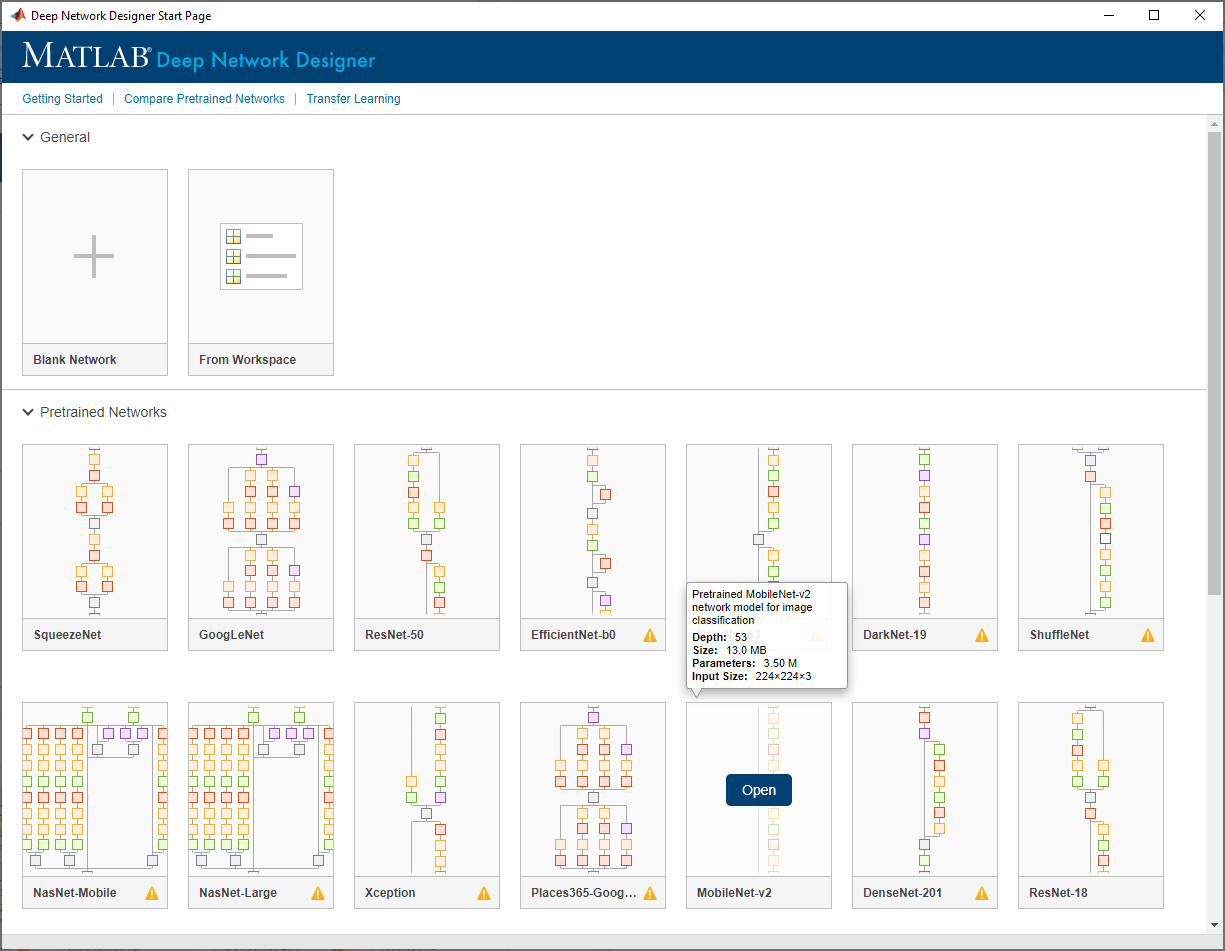

The network is loaded in the *Deep Network Designer* and can be edited. The last 4 layers of the network will be replaced with 2 new layers. The original network is designed for classification and these last layers need to be replaced to modify the network for regression.

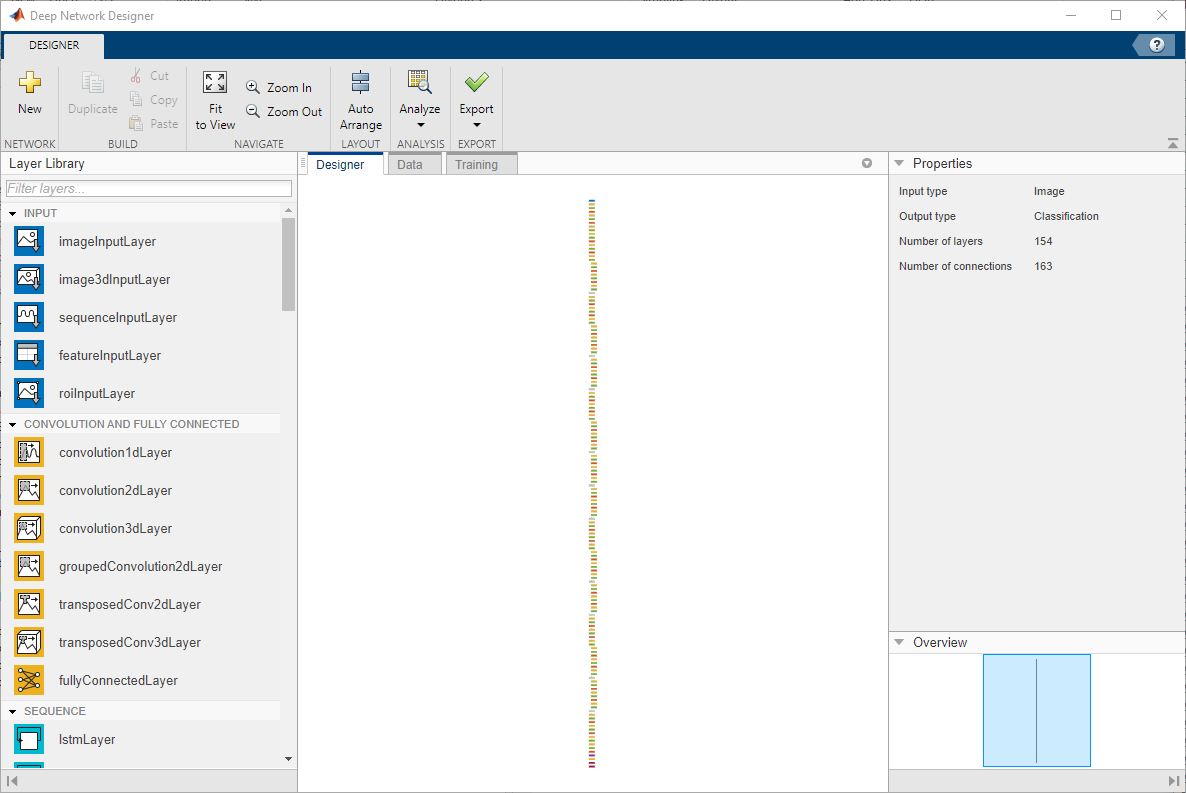

To do this, zoom and scroll to only show the last 5 layers. Select the last 4 layers and delete them.

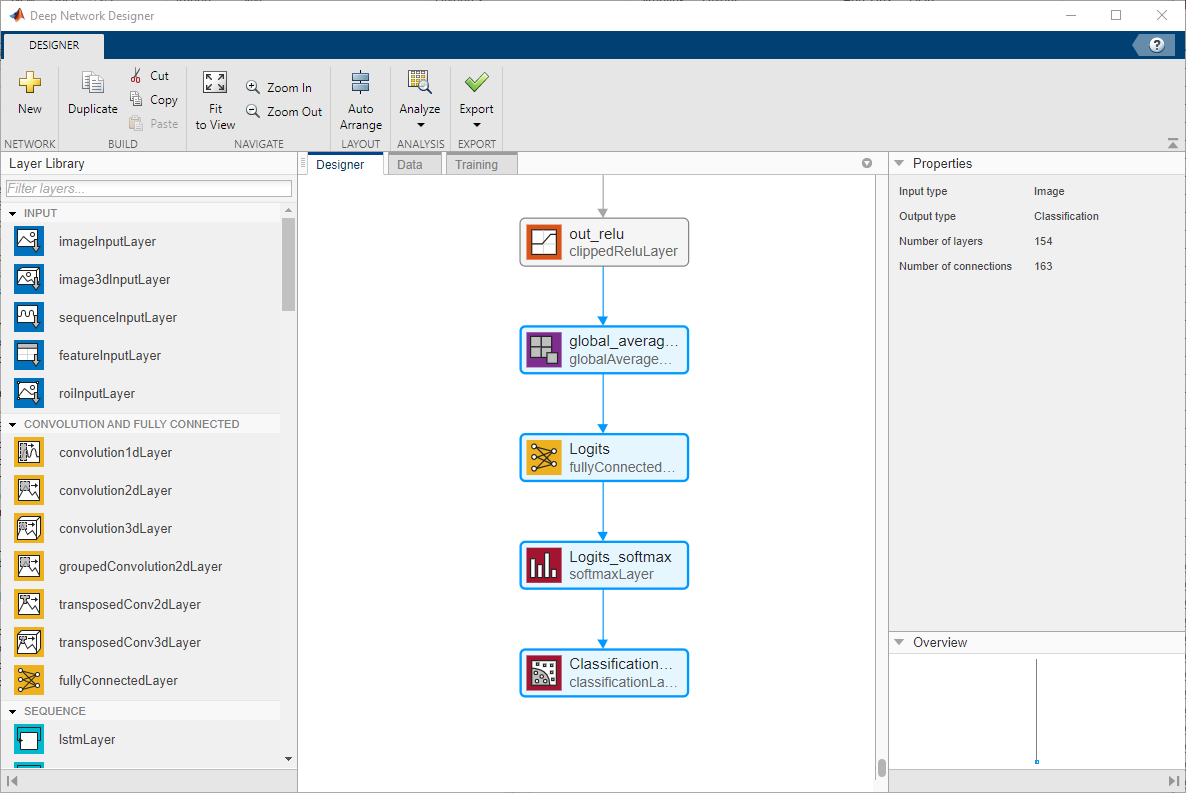

Add the first of the 2 new layers. Under the *Layer Library* on the left, find the *convolution2dLayer* in *Convolution and Fully Connected* section and drag it to the network and connect it to the end. Next, change the properties of the following settings:

- *FilterSize* = 7,7

- *NumFilters* = 22

- *Stride* = 7,7

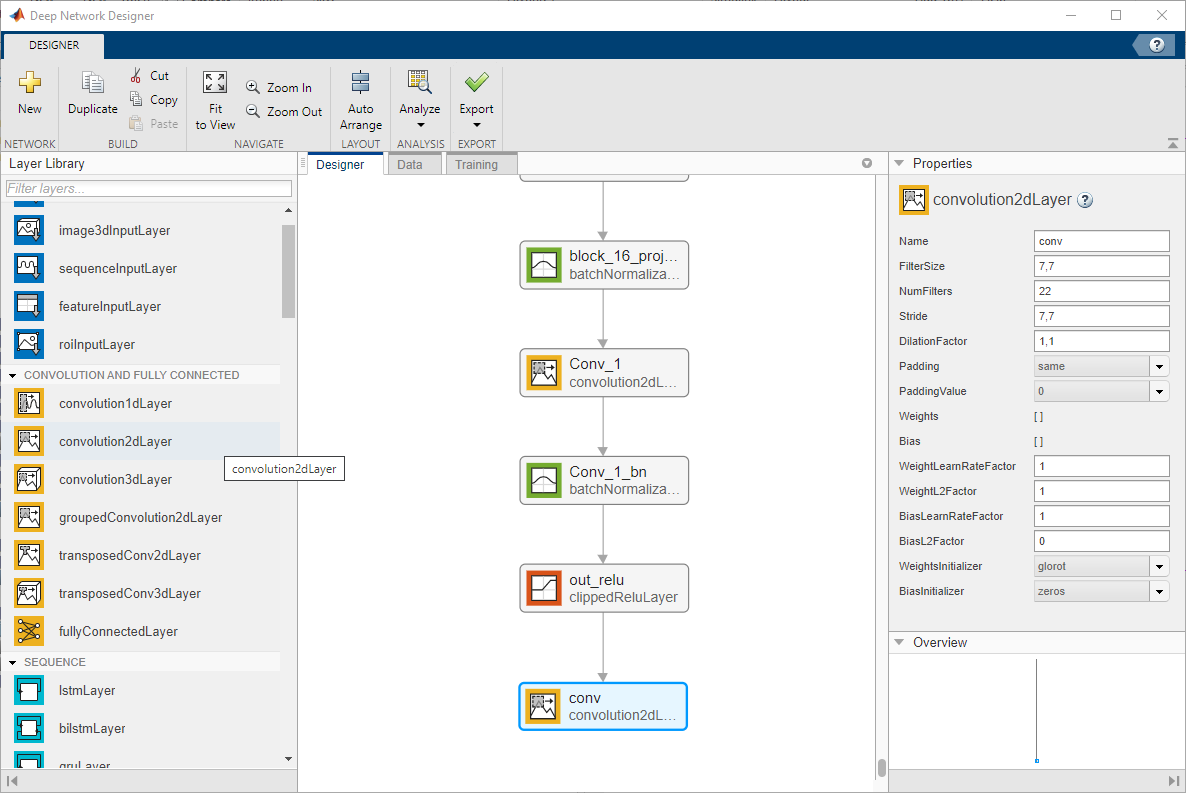

To add the second layer, in the *Layer Library* and find the *regressionLayer* in the *output* section and drag it to the network and connect it to the end.

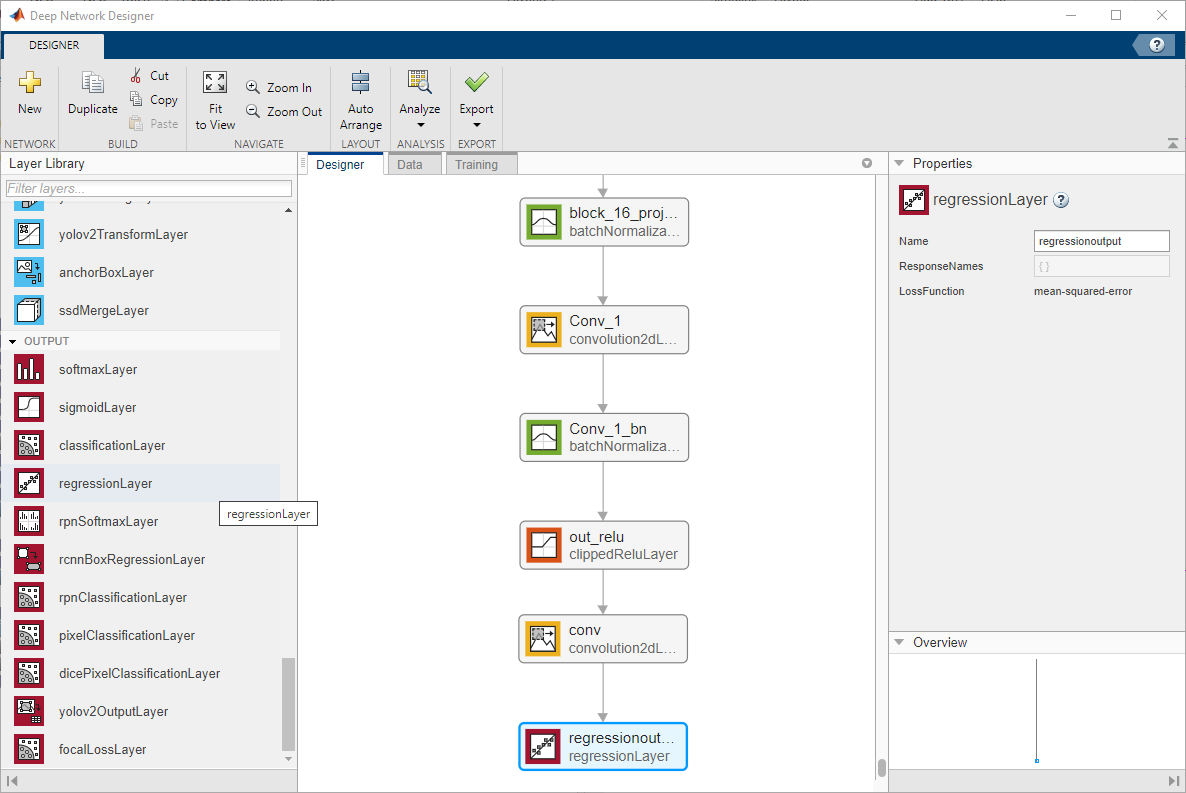

Finally, click on *Export* and select *Generate Code*. This generates a live script with the needed network. This file is saved as an m-file with the name *krNetwork.m* which also opens the save m-file. Modify the code as follows and save the file:

- Add the line *function [lgraph] = krNetwork()* to convert the m-file into a function

- comment out the last line *plot(lgraph)*

## Training

### Setup Training Options and Train network or Load Pretrained Network

Enable the checkbox and run this section to load the created network, setup the training options, and train the network. The training options are currently set to:

- Train for 150 epochs with a batch size of 48 on a GPU

- The data will shuffle every epoch

- The data will be validated against the validation data during the training process

- The learn rate is set to 1e-3 and will drop by 2% every epoch

The training parameters above were the same as in the reference paper [1].

To load an existing network, disable the checkbox and run this section to load the trained network netKRN150. This is a network that has already been trained for 150 epochs with the below settings. 

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:14 |       587.22 |       316.28 |  172415.6719 |   50016.5352 |          0.0010 |
|       1 |          10 |       00:01:32 |       267.07 |              |   35662.5078 |              |          0.0010 |
|       1 |          20 |       00:01:50 |       282.20 |              |   39818.7383 |              |          0.0010 |
|       1 |          30 |       00:02:08 |       278.40 |              |   38752.3047 |   

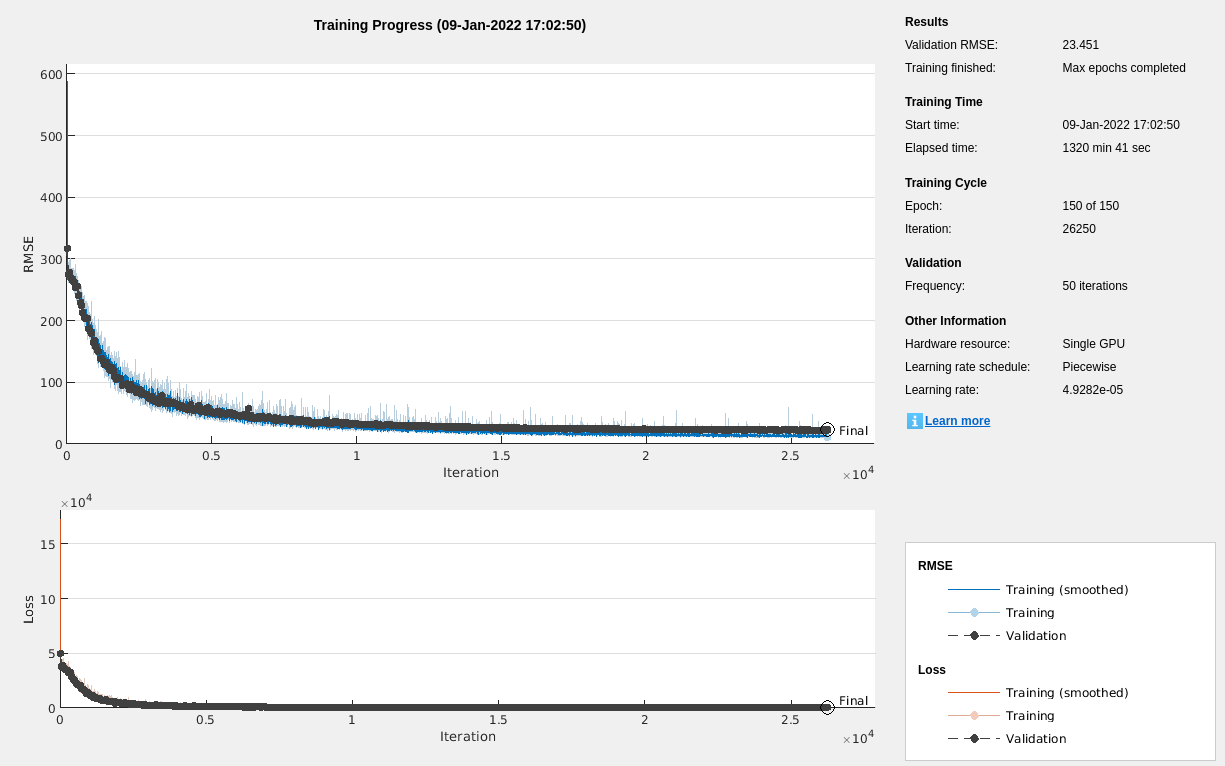

doTraining = true;
if doTraining
    lgraphKRN = krNetwork();

    options = trainingOptions("rmsprop","InitialLearnRate",1e-3,"MaxEpochs",150,"MiniBatchSize",48,"Shuffle","every-epoch",...
        "VerboseFrequency",10,"ValidationData",cdsKRNValPre,"plots","training-progress",...
        "L2Regularization",5e-5,"LearnRateSchedule","piecewise","LearnRateDropFactor",0.98,"LearnRateDropPeriod",1);
    
    netKRN = trainNetwork(cdsKRNTrainAug,lgraphKRN,options);
else
    load("network_trained_KRN.mat");
    netKRN = netKRN150;
end

### Evaluate Trained Network

Run this section to evaluate the performance of the network.

The network is tested on the preprocessed test datastore which the network has not seen. The error between the groundtruth and the results are calculated and the root mean square error (RMSE) is calculated for each image. The RMSE is then plotted as a histogram.

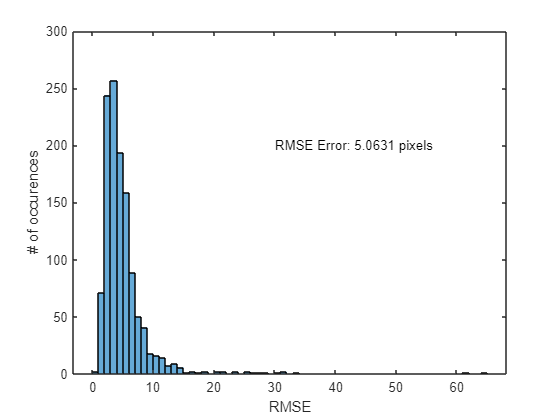

rmse = zeros(1,size(imdsKRNTest.Files,1));

reset(cdsKRNTestPre);
imageSelectorKRNTest = 0;
while hasdata(cdsKRNTestPre)
    imageSelectorKRNTest = imageSelectorKRNTest + 1;

    cdsKRNTestPreTemp = read(cdsKRNTestPre);
    imgKRNTestCrop = cdsKRNTestPreTemp{1};
    pointsKRNTestCrop = cdsKRNTestPreTemp{2};
    
    ptdsResults = double(predict(netKRN,imgKRNTestCrop));
    predError =  pointsKRNTestCrop - ptdsResults;
    rmse(1,imageSelectorKRNTest) = sqrt(mean(predError'.^2));
end


figure(); histogram(rmse)
xlabel("RMSE")
ylabel("# of occurences")
text(30,200,['RMSE Error: ', num2str(mean(rmse)),' pixels'])

## Test Network

Select an image from the test datastore and run it to test the network on previously images it hasn't previously seen

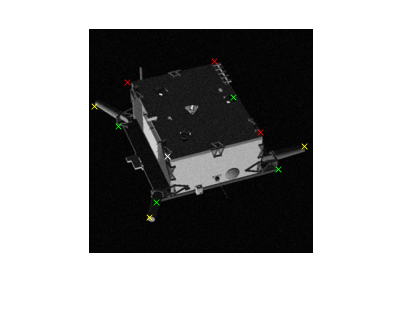

imageSelectorKRNTest = 3;
imgKRNTest = readimage(imdsKRNTest,imageSelectorKRNTest);
[imgKRNTestCrop,~] = preprocessData(readimage(imdsKRNTest,imageSelectorKRNTest),ptdsKRNTest.readall{imageSelectorKRNTest,:},rsz);
pointsKRNCameraRef = double(predict(netKRN,imgKRNTestCrop));
figure(); plotter_Points_Image(imgKRNTestCrop,pointsKRNCameraRef);

# Helper Functions

## partitionData Helper Function

The images and points data are randomly seperated into train, validation and test datastores using a helper function *partitionData.*

function [imdsTrain, imdsVal, imdsTest, ptdsTrain, ptdsVal, ptdsTest] = partitionData(imds,points,numTrainValTestFiles)

% Set initial random state for example reproducibility.
rng(0);

numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use predecided number of the images for training, validation and testing.
if numTrainValTestFiles < 1
    numTrain = round(numTrainValTestFiles(1)*numFiles);
    numVal = round(numTrainValTestFiles(2)*numFiles);
else
    numTrain = numTrainValTestFiles(1);
    numVal = numTrainValTestFiles(2);
end
trainIdx = shuffledIndices(1:numTrain);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores.
trainImages = imds.Files(trainIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Create points label datastores.
trainLabels = points(trainIdx,:);
valLabels = points(valIdx,:);
testLabels = points(testIdx,:);

ptdsTrain = arrayDatastore(trainLabels);
ptdsVal = arrayDatastore(valLabels);
ptdsTest = arrayDatastore(testLabels);

end

## preprocessDataCds Helper Function

The *preprocessDataCds* function is used to crop the images and resize them to 224 x 224 and modify the points for the resized images. The function is meant for combined datastores.

function dataOut = preprocessDataCds(dataIn,rsz)

dataOut = cell([size(dataIn,1),2]);

for idx = 1:size(dataIn,1)
    img = dataIn{idx,1};
    points = dataIn{idx,2};

    imgSize =size(img);
    bbox = generator_BBox_Image(imgSize,points(1:11),points(12:22));
    
    imgTemp = imcrop(img,bbox);
    imgTemp = imresize(imgTemp,rsz);
    imgPre = repmat(imgTemp,[1,1,3]);

    pointsCrop(1:11) = (points(1:11) - bbox(1)).*rsz(1)./max(bbox(3),bbox(4))';
    pointsCrop(12:22) = (points(12:22) - bbox(2)).*rsz(2)./max(bbox(3),bbox(4))';
    
    dataOut(idx,:) = {imgPre,pointsCrop};
end

end

## augmentData Helper Function

This *augmentData* function allows the same data to be randomly modified everytime it is called by the training network. The augmentation applied are random contrast, brightness and noise changes within a preset limit, and random 90 degree rotations.

function dataOut = augmentData(dataIn)

dataOut = cell([size(dataIn,1),2]);

for idx = 1:size(dataIn,1)
    img = dataIn{idx,1};
    points = dataIn{idx,2};
    
    img = jitterColorHSV(img,"Contrast",[0.5 2],"Brightness",[0 0.25]);
    img = imnoise(img,"gaussian");
    
    randRot = randi(4)-1;
    img = rot90(img,randRot);

    imgSize = size(img);
    xShift = points(1:11) - imgSize(1)/2;
    yShift = points(12:22) - imgSize(2)/2;
    XShiftRot =  xShift*cosd(randRot*90) + yShift*sind(randRot*90);
    YShiftRot = -xShift*sind(randRot*90) + yShift*cosd(randRot*90);
    XRot = XShiftRot + imgSize(1)/2;
    YRot = YShiftRot + imgSize(2)/2;
    points = [XRot YRot];
    
    dataOut(idx,:) = {img,points};
end

end

## preprocessData Helper Function

The *preprocessDataCds* function is used to crop the images and resize them to 224 x 224 and modify the points for the resized images. The function is meant for individual images and points.

function [imgCrop,pointsCrop] = preprocessData(img,points,rsz)

imgSize =size(img);
bbox = generator_BBox_Image(imgSize,points(1:11),points(12:22));

imgTemp = imcrop(img,bbox);
imgTemp = imresize(imgTemp,rsz);
imgCrop = repmat(imgTemp,[1,1,3]);

pointsCrop(1:11) = (points(1:11) - bbox(1)).*rsz(1)./max(bbox(3),bbox(4))';
pointsCrop(12:22) = (points(12:22) - bbox(2)).*rsz(2)./max(bbox(3),bbox(4))';

end